# Week 7b

**QEA Day Assignment**

**Ari Porad**

syms V(x,y)
V(x,y) = log(sqrt(x^2 + y^2)) - log(sqrt((x - 1)^2 + y^2)- log(sqrt((x - 2)^2 + (y-3)^2)))

$$V(x, y) = \log\left(\sqrt{x^{2}+y^{2}}\right)-\log\left(\sqrt{{\left(x-1\right)}^{2}+y^{2}}-\log\left(\sqrt{{\left(x-2\right)}^{2}+{\left(y-3\right)}^{2}}\right)\right)$$

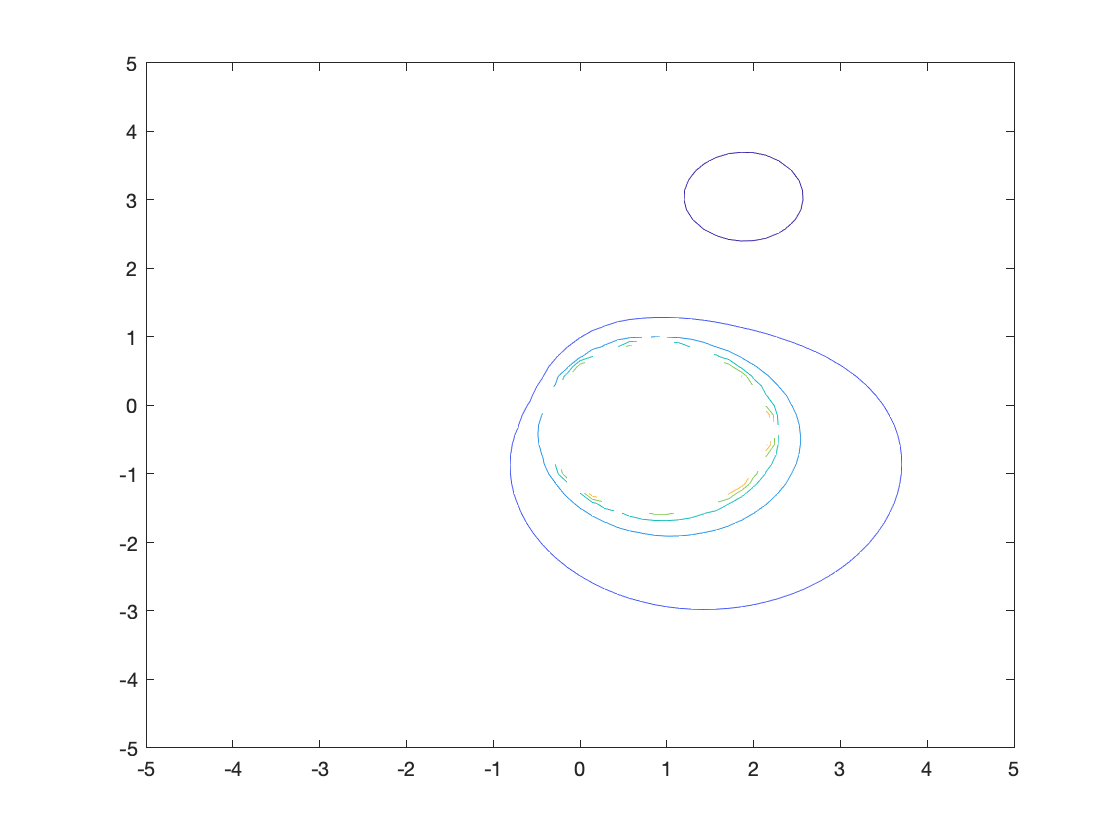

figure; clf;
fcontour(V);

figure; clf;
% % % % n = 20
grad = matlabFunction([diff(V, x); diff(V, y)])

grad = function_handle with value:
    @(x,y)[x./(x.^2+y.^2)+(((x.*2.0-2.0).*1.0./sqrt((x-1.0).^2+y.^2))./2.0-(x.*2.0-4.0)./((x-2.0).^2.*2.0+(y-3.0).^2.*2.0))./(log(sqrt((x-2.0).^2+(y-3.0).^2))-sqrt((x-1.0).^2+y.^2));y./(x.^2+y.^2)+(y.*1.0./sqrt((x-1.0).^2+y.^2)-(y.*2.0-6.0)./((x-2.0).^2.*2.0+(y-3.0).^2.*2.0))./(log(sqrt((x-2.0).^2+(y-3.0).^2))-sqrt((x-1.0).^2+y.^2))]



[xs, ys] = meshgrid(linspace(-5, 5, n), linspace(-5, 5, n))

xs =    -5.0000   -4.4737   -3.9474   -3.4211   -2.8947   -2.3684   -1.8421   -1.3158   -0.7895   -0.2632    0.2632    0.7895    1.3158    1.8421    2.3684    2.8947    3.4211    3.9474    4.4737    5.0000
   -5.0000   -4.4737   -3.9474   -3.4211   -2.8947   -2.3684   -1.8421   -1.3158   -0.7895   -0.2632    0.2632    0.7895    1.3158    1.8421    2.3684    2.8947    3.4211    3.9474    4.4737    5.0000
   -5.0000   -4.4737   -3.9474   -3.4211   -2.8947   -2.3684   -1.8421   -1.3158   -0.7895   -0.2632    0.2632    0.7895    1.3158    1.8421    2.3684    2.8947    3.4211    3.9474    4.4737    5.0000
   -5.0000   -4.4737   -3.9474   -3.4211   -2.8947   -2.3684   -1.8421   -1.3158   -0.7895   -0.2632    0.2632    0.7895    1.3158    1.8421    2.3684    2.8947    3.4211    3.9474    4.4737    5.0000
   -5.0000   -4.4737   -3.9474   -3.4211   -2.8947   -2.3684   -1.8421   -1.3158   -0.7895   -0.2632    0.2632    0.7895    1.3158    1.8421    2.3684    2.8947    3.4211    3.9474    4.4737 

ys =    -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000
   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737
   -3.9474   -3.9474   -3.9474   -3.9474   -3.9474   -3.9474   -3.9474   -3.9474   -3.9474   -3.9474   -3.9474   -3.9474   -3.9474   -3.9474   -3.9474   -3.9474   -3.9474   -3.9474   -3.9474   -3.9474
   -3.4211   -3.4211   -3.4211   -3.4211   -3.4211   -3.4211   -3.4211   -3.4211   -3.4211   -3.4211   -3.4211   -3.4211   -3.4211   -3.4211   -3.4211   -3.4211   -3.4211   -3.4211   -3.4211   -3.4211
   -2.8947   -2.8947   -2.8947   -2.8947   -2.8947   -2.8947   -2.8947   -2.8947   -2.8947   -2.8947   -2.8947   -2.8947   -2.8947   -2.8947   -2.8947   -2.8947   -2.8947   -2.8947   -2.8947 

xs = reshape(xs, [1, n ^ 2])

xs =    -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -4.4737   -3.9474   -3.9474   -3.9474   -3.9474   -3.9474   -3.9474   -3.9474   -3.9474   -3.9474   -3.9474


ys = reshape(ys, [1, n^2])

ys =    -5.0000   -4.4737   -3.9474   -3.4211   -2.8947   -2.3684   -1.8421   -1.3158   -0.7895   -0.2632    0.2632    0.7895    1.3158    1.8421    2.3684    2.8947    3.4211    3.9474    4.4737    5.0000   -5.0000   -4.4737   -3.9474   -3.4211   -2.8947   -2.3684   -1.8421   -1.3158   -0.7895   -0.2632    0.2632    0.7895    1.3158    1.8421    2.3684    2.8947    3.4211    3.9474    4.4737    5.0000   -5.0000   -4.4737   -3.9474   -3.4211   -2.8947   -2.3684   -1.8421   -1.3158   -0.7895   -0.2632


arrows = grad(xs, ys)

arrows =     0.0297    0.0314    0.0328    0.0337    0.0339    0.0333    0.0317    0.0293    0.0264    0.0231    0.0200    0.0172    0.0149    0.0131    0.0118    0.0109    0.0102    0.0098    0.0094    0.0092    0.0339    0.0364    0.0387    0.0404    0.0412    0.0409    0.0392    0.0361    0.0321    0.0275    0.0231    0.0192    0.0162    0.0139    0.0123    0.0112    0.0104    0.0098    0.0094    0.0092    0.0386    0.0424    0.0460    0.0490    0.0510    0.0515    0.0498    0.0460    0.0404    0.0338
    0.0045    0.0027    0.0005   -0.0021   -0.0049   -0.0076   -0.0101   -0.0120   -0.0130   -0.0132   -0.0126   -0.0114   -0.0100   -0.0084   -0.0070   -0.0059   -0.0049   -0.0042   -0.0037   -0.0034    0.0068    0.0047    0.0020   -0.0012   -0.0048   -0.0087   -0.0123   -0.0151   -0.0168   -0.0171   -0.0162   -0.0144   -0.0123   -0.0101   -0.0083   -0.0067   -0.0056   -0.0047   -0.0040   -0.0036    0.0099    0.0077    0.0047    0.0007   -0.0041   -0.0095   -0.0148   -0.0193   -0.0221

ax = arrows(1, :)

ax =     0.0297    0.0314    0.0328    0.0337    0.0339    0.0333    0.0317    0.0293    0.0264    0.0231    0.0200    0.0172    0.0149    0.0131    0.0118    0.0109    0.0102    0.0098    0.0094    0.0092    0.0339    0.0364    0.0387    0.0404    0.0412    0.0409    0.0392    0.0361    0.0321    0.0275    0.0231    0.0192    0.0162    0.0139    0.0123    0.0112    0.0104    0.0098    0.0094    0.0092    0.0386    0.0424    0.0460    0.0490    0.0510    0.0515    0.0498    0.0460    0.0404    0.0338


ay = arrows(2, :)

ay =     0.0045    0.0027    0.0005   -0.0021   -0.0049   -0.0076   -0.0101   -0.0120   -0.0130   -0.0132   -0.0126   -0.0114   -0.0100   -0.0084   -0.0070   -0.0059   -0.0049   -0.0042   -0.0037   -0.0034    0.0068    0.0047    0.0020   -0.0012   -0.0048   -0.0087   -0.0123   -0.0151   -0.0168   -0.0171   -0.0162   -0.0144   -0.0123   -0.0101   -0.0083   -0.0067   -0.0056   -0.0047   -0.0040   -0.0036    0.0099    0.0077    0.0047    0.0007   -0.0041   -0.0095   -0.0148   -0.0193   -0.0221   -0.0227


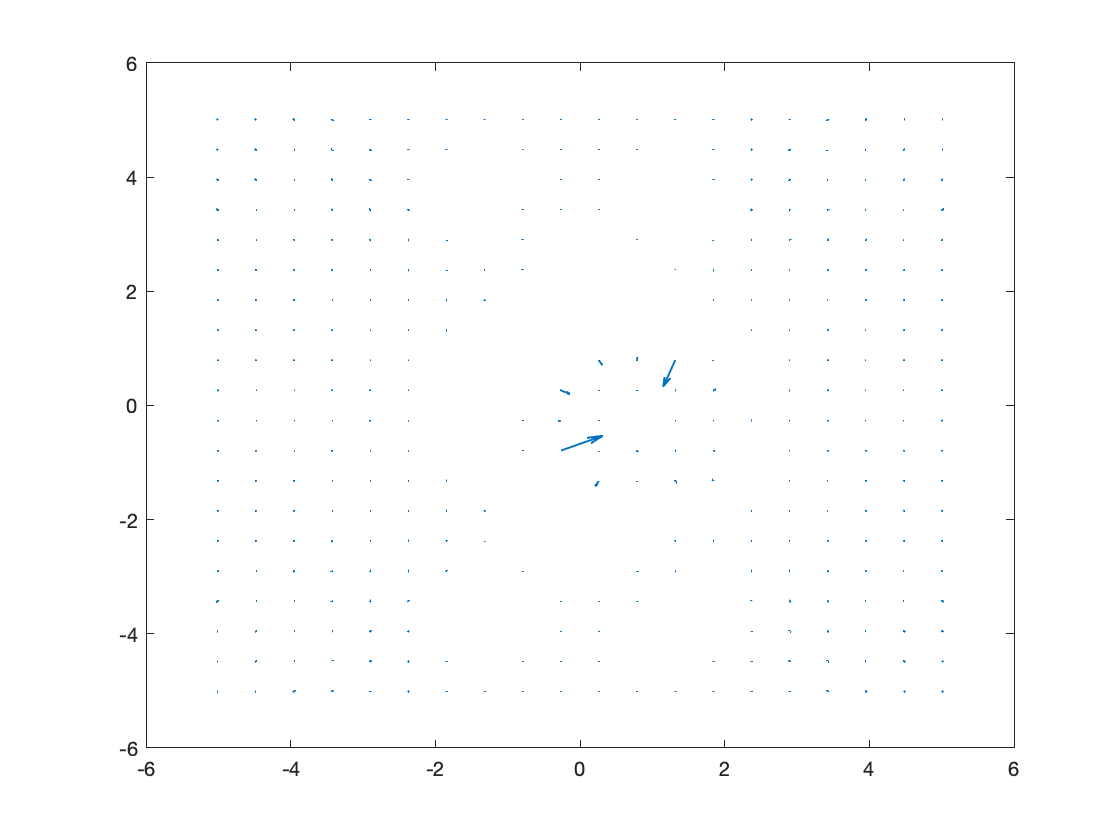


quiver(xs, ys, xs + ax, ys + ay, 'LineWidth', 1, "ShowArrowHead", "on", "MarkerSize", 1)